# `Linearized Longitudinal Vehicle Control from gain scheduled LTI systems modeled on more complex dynamics`

`Simulink & Matlab`

`Brian Lesko, Graduate Researcher and Teaching Associate, Masters of mechanical engineering student `

`8/8/23`

` Ohio State University`

`with use of Robust Controls of Mechatronic Systems by Dr. Levent Guvenc`

clc; clear; close all;
load('longitudinalModelData80923.mat')
longitudinalModelData80823

longitudinalModelData80823 = 107×11 table
     Vs     Tm_Tb       K          T          rmse       time     avg_acc       dX        Ve      Tm     Tb
    ____    _____    ________    ______    __________    ____    _________    ______    ______    ___    __

       0       0      0.52277    198.47      0.013211      0             0         0         0      0    0 
    0.01      55      0.53809    111.13      0.010918    600      0.049325     14695    29.605     55    0 
    0.01      80      0.48331    85.937     0.0091168    600      0.064442     20125    38.675     80    0 
    0.01     105      0.43781    71.785    

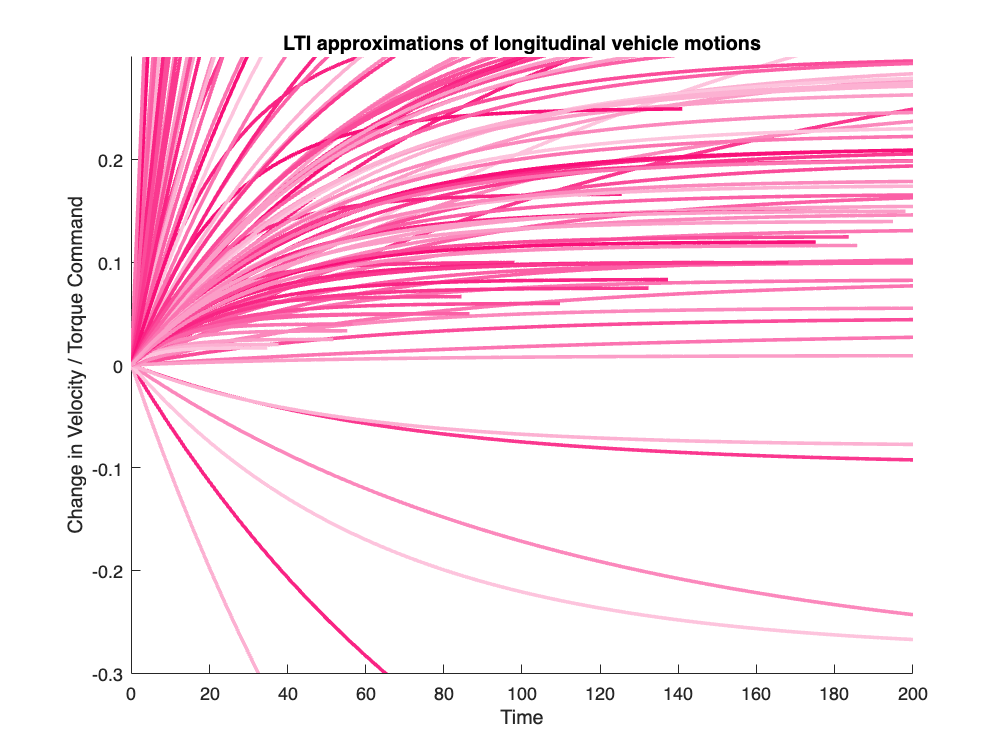

% The first step is to interpolate between Vs and Tm_Tb values to get more appropriate K and T values
% A cool animation of a changing curve would show this off greatly. Lets first plot all the LTI systems. 
longModData = longitudinalModelData80823;
params = [longModData.K,longModData.T];
hold on;
plotLTI(params), axis([0 200 -.3 .3])
xlabel('Time'), ylabel('Change in Velocity / Torque Command'), title('LTI approximations of longitudinal vehicle motions')

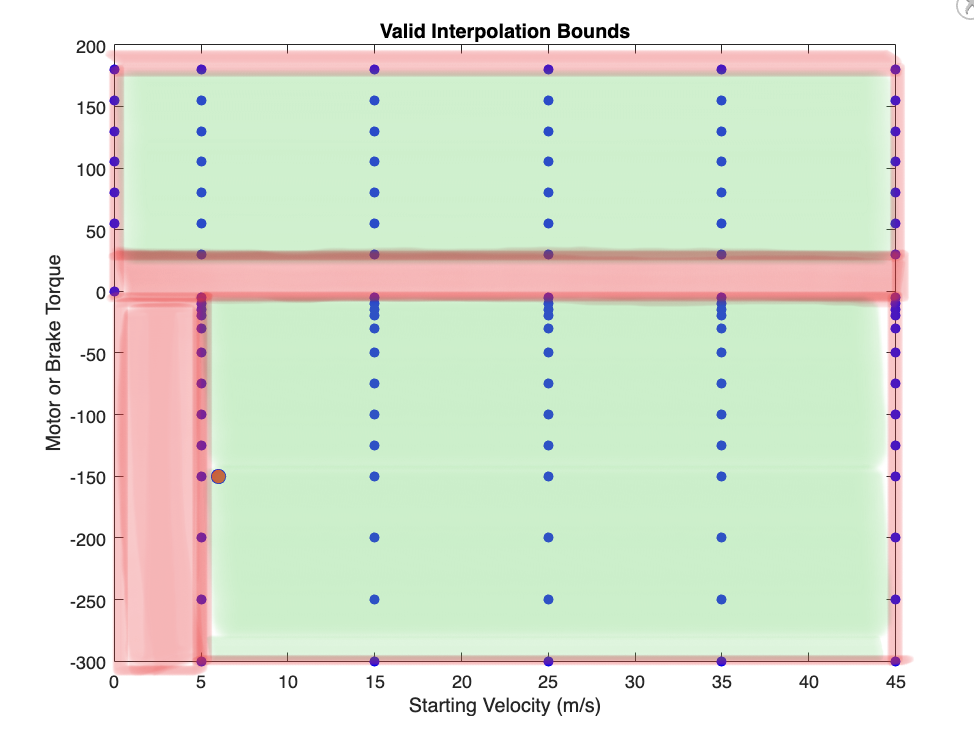

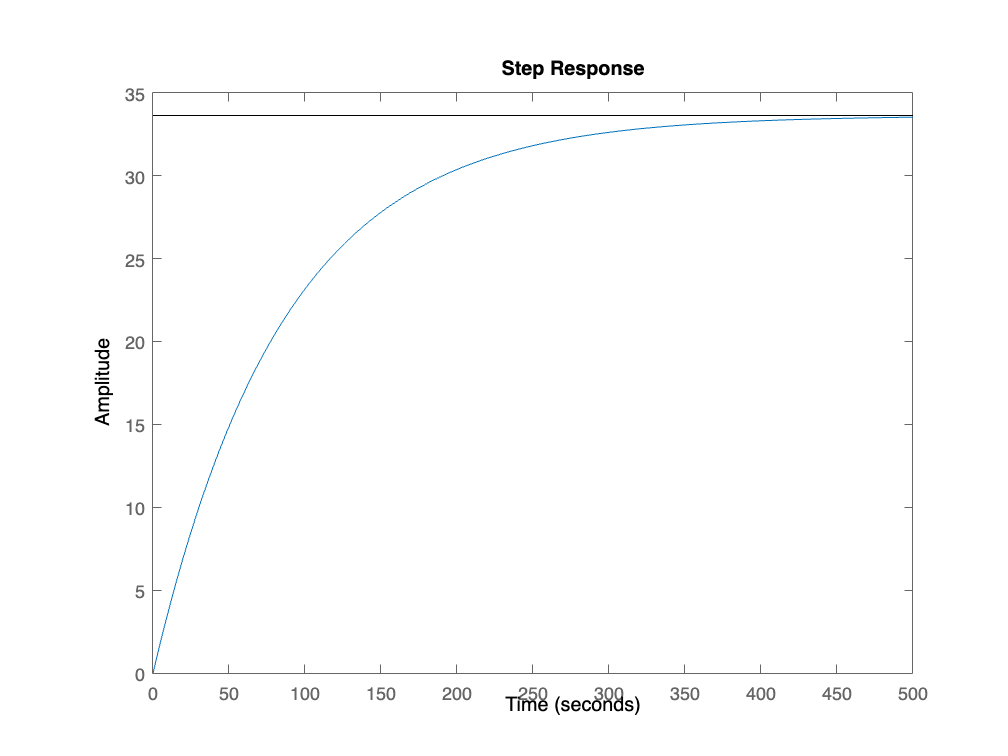

vstart = 0.1;
torque = 80;

%plotInterpolationParameters(V,T,1,1,longModData.Vs,longModData.Tm_Tb,longModData.K,longModData.Tm_Tb)

K = bilinearInterpolation(vstart,torque,longModData.K,longModData.Vs,longModData.Tm_Tb);
T = bilinearInterpolation(vstart,torque,longModData.T,longModData.Vs,longModData.Tm_Tb);

s = tf('s');
sys = K/(T*s+1);

%the open loop response
figure
step(sys*torque)

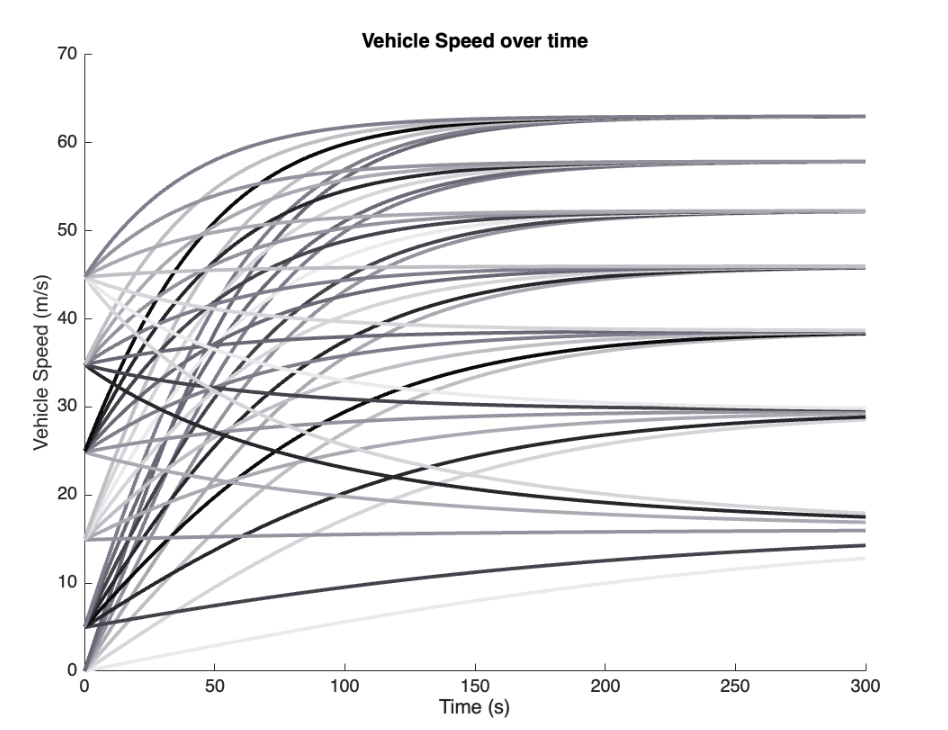

This result is consistent with the original simualtions! 

Lets check the closed loop response, with a step input desired velocity of 30m/s

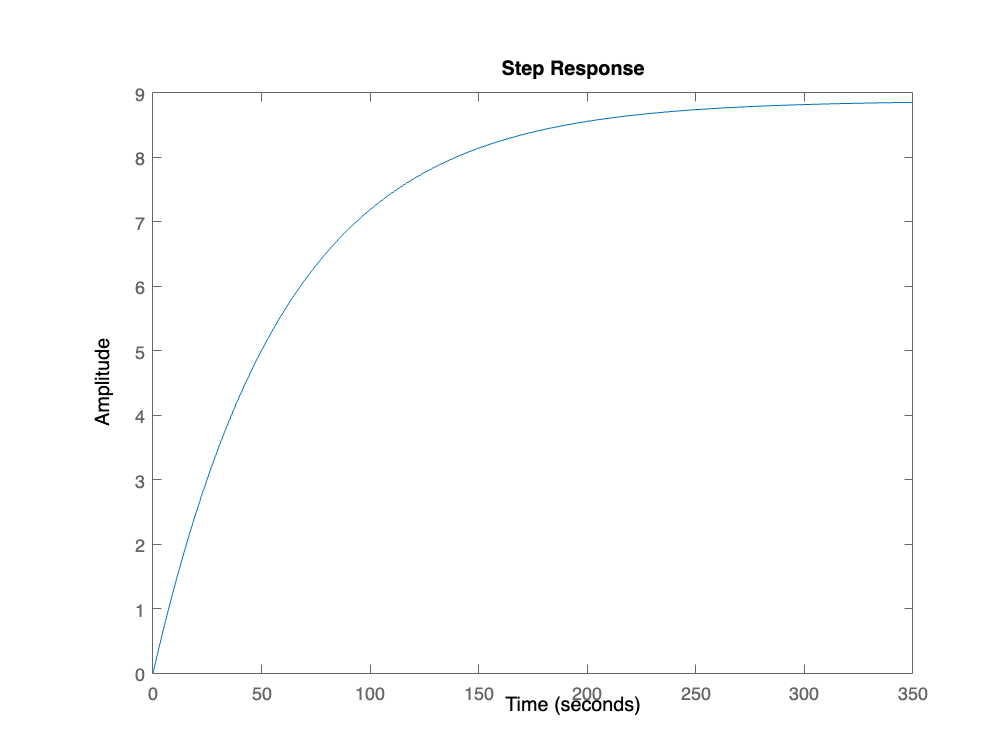

H = feedback(sys,1);
step(30*H)

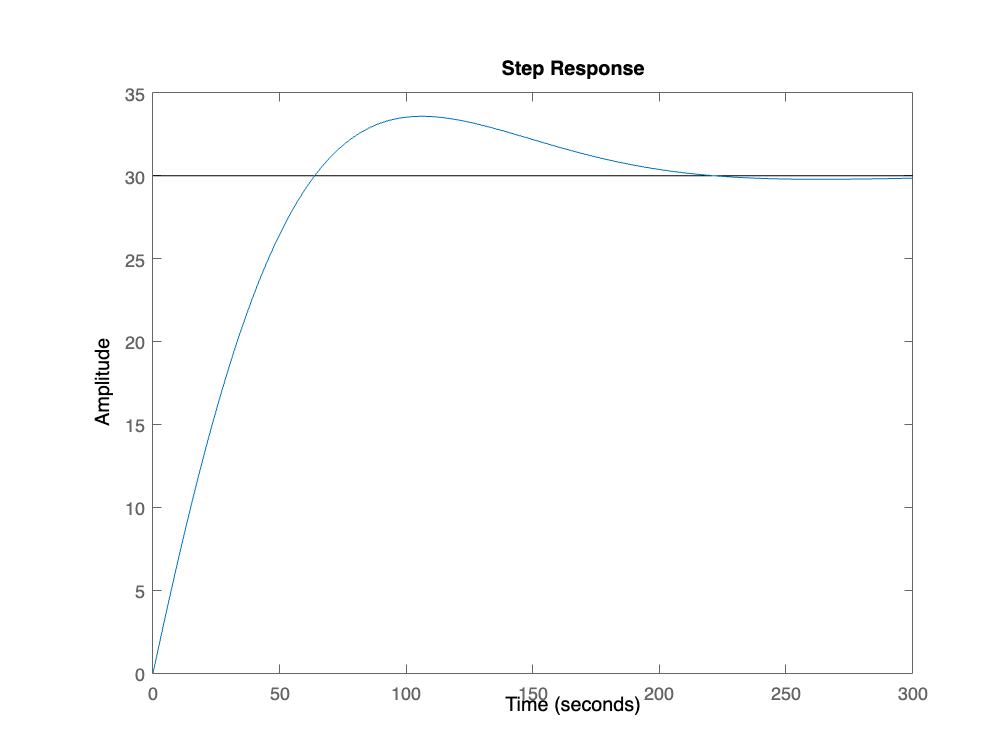

% Theres some steady state error so we need at least a KI controller, add
% PID to help eliminate overshoot
C = pidtune(H,'PID');
PIDsys = feedback(C*sys,1);
step(30*PIDsys)

Great! we have achieved steady state velocity control, but maybe the derivative needs to be stronger to reduce overshoot. 

We also ignored that motor torque changes the plant in this system!

# Functions 

function plotLTI(params)
    n = length(params(:,1));
    colors2 = getColors2();
    for i = 1:1:n
        param = params(i,:);
        K = param(1); T = param(2);
    
        s = tf('s');
        LTI = K/ (T*s + 1);
        [h,g] = step(LTI);
        
        color2 = colors2(i);
        plot(g, h, 'Color', color2,'LineWidth',2)
    end 
end 
function colors = getColors()
    a = "#0A0A0A"; % night
    d = "#27272B"; % raisin black
    g = "#43434C"; % onyx
    j = "#696977"; % dim gray
    l = "#7D7D8C"; % taupe gray
    m = "#93939F"; % cool gray
    n = "#A9A9B2"; % french gray
    o = "#BEBEC5"; % french gray
    p = "#D4D4D9"; % platinum
    q = "#EAEAEC"; % anti-flash white

    colors = [q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a]; 
end     

function colors = getColors2()
    a = "#F91079"; 
    d = "#F92484"; 
    g = "#FA388F"; 
    j = "#FA4C9A"; 
    l = "#FB60A6"; 
    m = "#FB74B1"; 
    n = "#FB88BC"; 
    o = "#FB9DC7"; 
    p = "#FCB1D2"; 
    q = "#FDC4DD"; 

    colors = [q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a]; 
end

# Bilinear Interpolation for this script

function Zinterp = bilinearInterpolation(xs,ys,Z,X,Y)
    Zinterps = zeros(length(xs));
    for i = 1:1:length(xs)
        x = xs(i);
        y = ys(i);
        
        % first interpolation
            % find indicies of x group immediately above and below the picked x
            diffs = X - x;
            positiveDifferences = diffs(diffs > 0); % Filter out only the positive differences
            smallestPositiveDifference = min(positiveDifferences); % Find the smallest positive difference
            ind_closestGreater = (round(diffs,1) == round(smallestPositiveDifference,1));
                closestGreater = X(ind_closestGreater); % Get the values from x
        
                % Closest Y's above and below in the set of X's
                Yg = Y(ind_closestGreater);
                d = (Yg - y); 
                dpm1 = min(d(d>0)); 
                ind_dpm1 = (round(d,1) == round(dpm1,1));
                closestYGreaterinXGreater = Yg(ind_dpm1); %Above
        
                d = (Yg - y); dpm2 = max(d(d<0)); ind_dpm2 = (round(d,1) == round(dpm2,1));
                closestYLessinXGreater = Yg(ind_dpm2); %Below
        
                %fraction 
                Yrange = (closestYGreaterinXGreater-closestYLessinXGreater);
                frac = (y - closestYLessinXGreater)/Yrange;
        
                %Y Parameter Interpolation 1
                Zg = Z(ind_closestGreater);
                Zgl = min(Zg(ind_dpm1),Zg(ind_dpm2)); Zgg = max(Zg(ind_dpm1),Zg(ind_dpm2));
                Zrange = Zgg - Zgl;
                Zinterp1 = Zrange*frac + Zgl;
        
            diffs = X - x;
            negativeDifferences = diffs(diffs < 0); % Filter out only the negative differences
            largestNegativeDifference = max(negativeDifferences); % Find the largest negative difference
            ind_closestLess = (round(diffs,1) == round(largestNegativeDifference,1));
                closestLessThan = X(ind_closestLess); % Get the values from x
        
                Yl = Y(ind_closestLess);
                d = (Yg - y); dpm = max(d(d<0)); ind_dpm = (round(d,1) == round(dpm,1));
                closestYLessinXLess = Yl(ind_dpm);
        
                d = (Yg - y); dpm = min(d(d>0)); ind_dpm = (round(d,1) == round(dpm,1));
                closestYGreaterinXLess = Yl(ind_dpm);
        
                %fraction 
                Yrange = (closestYGreaterinXLess-closestYLessinXLess);
                frac = (y - closestYLessinXLess)/Yrange;
        
                %Y Parameter Interpolation 2
                Zl = Z(ind_closestLess);
                Zll = min(Zl(ind_dpm1),Zl(ind_dpm2)); Zlg = max(Zl(ind_dpm1),Zl(ind_dpm2));
                Zrange = Zlg - Zll;
                Zinterp2 = Zrange*frac + Zll;
        
           % X interpolation 
           Xrange = max(closestGreater) - min(closestLessThan);
           frac = (x - min(closestLessThan))/Xrange;
           Zmin = min(Zinterp1,Zinterp2); Zmax = max(Zinterp1,Zinterp2);
           Zrange = Zmax - Zmin;
           Zinterp = frac*Zrange + Zmin;
        
           Zinterps(i) = Zinterp;
    end 
end 

# Single Linear Interpolation 

function [y possible] = linearInterpolation(x,X,Y)
    d = (X - x); % differences

    dpm1 = min(d(d>0)); % above 
    dpm2 = max(d(d<0)); % below

    % interpolation is possible
    if (length(dpm1) > 0 && length(dpm2) > 0)

        ind_closestGreater = (round(d,1) == round(dpm2,1));
        x1 = min(X(ind_closestGreater)); % the x closest Greater
        y1 = max(Y(ind_closestGreater)); % the z of the x closest Greater

        ind_closestLess = (round(d,1) == round(dpm2,1));
        x2 = max(X(ind_closestLess)); % the x closest Less
        y2 = max(Y(ind_closestLess));% the z of the x closest Less

        y = y1 + (x - x1) * (y2-y1)/(x2-x1);
    end
    if length(dpm2) < 1 % y is greater than Y bound 
        y = false;
    end 
    if length(dpm1) < 1 % y is less than Y bounds 
        y = false;
    end 
end 


# Extrapolation work 

 % % Extrapolation is below range
 %    if length(dpm2) < 1 % then there are no numbers below xt
 %        warning('There are no entries below the target x, one sided interpolation is necessary')
 %        % find two above and go off slope
 %        ind_closestGreater = (round(d,1) == round(dpm2,1));
 %        x_closestGreater = min(x(ind_closestGreater));
 %        z_closestGreater = max(z(ind_closestGreater));
 % 
 %        dd = (d - dpm1); g = min(dd(dd>0)) + dpm1;
 %        ind_secondClosestGreater = (round(d,1) == round(g,1));
 %        x_secondClosestGreater = max(x(ind_secondClosestGreater));
 %        z_secondClosestGreater = max(z(ind_secondClosestGreater));
 % 
 %        zmin = min(z_closestGreater,z_secondClosestGreater); zmax = max(z_closestGreater,z_secondClosestGreater); 
 %        zrange = zmax - zmin;
 %        xrange = x_secondClosestGreater - x_closestGreater;
 %        dzdx = zrange/xrange;
 % 
 %        zt = dzdx * (-xt + x_closestGreater) + z_closestGreater;
 %    end 
 % 
 %    % Extrapolation is above range
 %    if length(dpm1) < 1 % then there are no numbers above xt
 %        warning('extrapolation is necessary')
 % 
 %        % find slope and go off numbers below only
 %        ind_closestLess = (round(d,1) == round(dpm2,1));
 %        x_closestLess = max(x(ind_closestLess)); %Below
 %        z_closestLess = max(z(ind_closestLess));
 % 
 %        dd = (d - dpm2); g = max(dd(dd<0)) + dpm2;
 %        ind_secondClosestLess = (round(d,1) == round(g,1));
 %        x_secondClosestLess = max(x(ind_secondClosestLess));
 %        z_secondClosestLess = max(z(ind_secondClosestLess));
 % 
 %        zmin = min(z_closestLess,z_secondClosestLess); zmax = max(z_closestLess,z_secondClosestLess); 
 %        zrange = zmax - zmin;
 %        xrange = x_closestLess - x_secondClosestLess;
 %        dzdx = zrange/xrange;
 % 
 %        zt = dzdx * (xt - x_closestLess) + z_closestLess;
 %    end 
 % 
 % 

 Get axis limits

function [x_min, x_max, y_min, y_max, z_min, z_max] = getAxisLimits()
    % Get the current axis handle
    ax = gca;

    % Retrieve the limits for each axis
    x_limits = xlim(ax);
    y_limits = ylim(ax);
    z_limits = zlim(ax);

    % Extract the minimum and maximum values for each axis
    x_min = x_limits(1);
    x_max = x_limits(2);
    y_min = y_limits(1);
    y_max = y_limits(2);
    z_min = z_limits(1);
    z_max = z_limits(2);
end


Plot Parameter Space 

function plotInterpolationParameters(x,y,z1,z2,X,Y,Z1,Z2)
    close all
    % Velocity Start Surface
    plot3(X,Y,Z1,'bo','MarkerFaceColor','b','MarkerSize',5)
    hold on 
    plot3(x,y,z1,'ro','MarkerFaceColor','r','MarkerSize',10)
    
    % Torque Command Surface 
    plot3(X,Y,Z2/10,'go','MarkerFaceColor','g','MarkerSize',5)
    hold on 
    plot3(x,y,z2/10,'ro','MarkerFaceColor','r','MarkerSize',10)
    
    %Asymptotic plane 
    [x_min, x_max, y_min, y_max, z_min, z_max] = getAxisLimits();
    fill3([x_min, x_max, x_max, x_min], [0, 0, 0, 0], [z_min, z_min, z_max, z_max], 'r'); alpha(0.5)
    
    view([40 30]), xlabel('Starting Velocity (m/s)'), ylabel('Motor or Brake Torque'), title('LTI parameters over the scheduling variables plane'), zlabel('Parameter Value'), legend('Parameter K gain','Interpolated K','Time Constant parameter','Interpolated Time constant','Asymptotic Plane')
end 